# HW 12

clear;clc;close;

## Load Data

cpU = readmatrix("Prob_3_1_cp_upper.xlsx")

cpU =          0
   -0.3500
   -0.4300
   -0.4800
   -0.7000
   -0.7600
   -0.7700
   -0.7500
   -0.7500
   -0.7300


xc = readmatrix("Prob_3_1_x_c.xlsx")

xc =          0
    0.0050
    0.0125
    0.0250
    0.0500
    0.0750
    0.1000
    0.1500
    0.2000
    0.2500


zcL = readmatrix("Prob_3_1_z_c_lower.xlsx")

zcL =          0
   -0.0144
   -0.0205
   -0.0269
   -0.0357
   -0.0421
   -0.0470
   -0.0543
   -0.0593
   -0.0626


zcU = readmatrix("Prob_3_1_z_c_upper.xlsx")

zcU =          0
    0.0204
    0.0307
    0.0416
    0.0560
    0.0656
    0.0731
    0.0841
    0.0921
    0.0978


## 3.3

% standard sea level
rho = 2.377*10^-3; %slugs/ft^3
g = 32.2; % ft/s
gamma = rho*g; % lbf/ft^3

Cp0 = min(cpU);
minCpIndex = find(cpU == Cp0); %find position of max velocity

syms M;
CpCrit = getCpCrit(M,gamma)

$$CpCrit = \frac{144115188075855872\,\left(\frac{1}{{\left(\frac{9007199254740992}{4848302440689657}-\frac{2772597876034223\,M^{2}}{3232201627126438}\right)}^{5972366350125367/72057594037927936}}-1\right)}{5515245013106581\,M^{2}}$$



CpPg = prandtlGlauertTransformation(Cp0,M);
CpKt = karmanTsienTransformation(Cp0,M);

MCritPg = vpasolve(CpCrit == CpPg, M)

 
MCritPg =
 
Empty sym: 0-by-1
 




M = linspace(0,1,1000);
CpCrit = arrayfun(@(m) getCpCrit(m,gamma),M);
CpPg = arrayfun(@(m) prandtlGlauertTransformation(Cp0,m), M);
CpKt = arrayfun(@(m) karmanTsienTransformation(Cp0,m), M);

% CpPgCrit = findClosestVectorIntersection(CpCrit,CpPg)
MCritPg = M(findClosestVectorIntersection(CpCrit,CpPg))

MCritPg = 0.7558

MCritKt = M(findClosestVectorIntersection(CpCrit,CpKt))

MCritKt = 0.7277

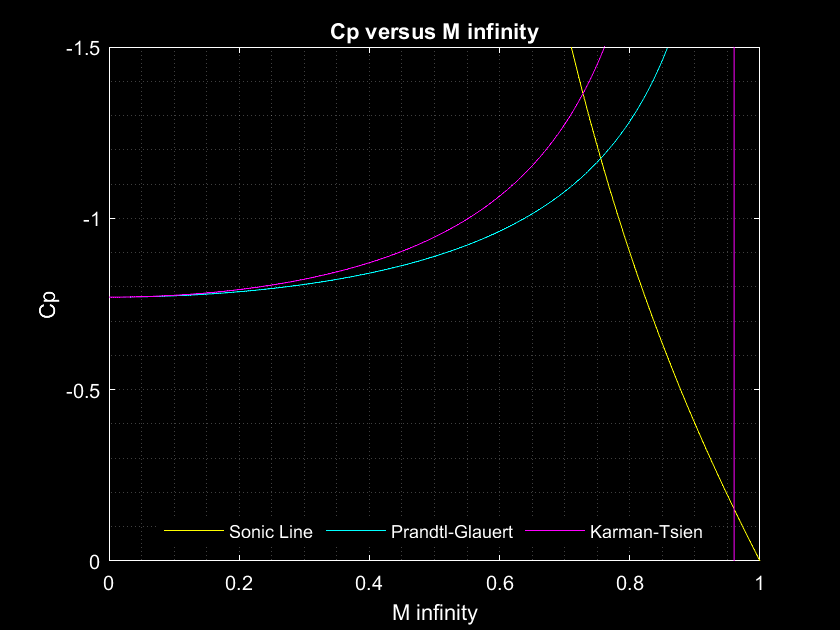


figure;
plot1(1) = plot(M,CpCrit,'y'); hold on;
plot1(2) = plot(M,CpPg,'c'); hold on;
plot1(3) = plot(M,CpKt,'magenta'); hold on;
%legend("Sonic Line","Prandtl-Glauert","Karman-Tsien");
set(plot1(1),'DisplayName','Sonic Line','Color',[1 1 0]); set(plot1(2),'DisplayName','Prandtl-Glauert','Color',[0 1 1]); set(plot1(3),'DisplayName','Karman-Tsien','Color',[1 0 1]);
axis([0,1,-1.5,0]); set(gca,'YDir','reverse');
title("Cp versus M infinity","Color",'w'); xlabel('M infinity','Color','w'); ylabel('Cp','Color','w')
set(gca, 'color','k', 'xcolor','w', 'ycolor','w'); set(gcf, 'color','k');
grid(gca,"minor"); box(gca,'on'); hold(gca,'off'); %axis(gca,'ij');
% Create legend
legend1 = legend(gca,'show'); set(legend1,'TextColor',[1 1 1],'Orientation','horizontal','Location','south','EdgeColor','none');

## 3.7

u = symunit;
M = 450 / (getSpdSoundAir(288.2) * double(unitConversionFactor(u.meter/u.sec, u.mile/u.hour)));
CpPg = prandtlGlauertTransformation(Cp0,M)

CpPg = -0.9546

CpKt = karmanTsienTransformation(Cp0,M)

CpKt = -1.0517